## Parámetros

syms q1(t) q2(t) t theta
syms m1 l1 lc1 I1 m2 l2 lc2 I2 g

## Cinematica directa y diferencial

%xy2 = @(q1,q2) [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)];
%xy2(0,pi/2)
%v1 = @(q1,vq1) [-lc1*sin(q1); lc1*cos(q1)].*vq1;
%v1(pi/2,1)
%v2 = @(q1,q2,vq1,vq2) [-l1*sin(q1)-lc2*sin(q1+q2) -lc2*sin(q1+q2); l1*cos(q1)+lc2*cos(q1+q2) lc2*cos(q1+q2)]*[vq1;vq2];
%v2(0,0,1,1)
xy1 = [lc1*cos(q1); lc1*sin(q1)]

$$xy1(t) = \left(\begin{array}{c} {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ {\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right) \end{array}\right)$$

xy2 = [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)]

$$xy2(t) = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

cdE = [l1*cos(q1)+l2*cos(q1+q2); l1*sin(q1)+l2*sin(q1+q2)]

$$cdE(t) = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

v1 = diff(xy1,t)

$$v1(t) = \left(\begin{array}{c} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

v2 = diff(xy2,t)

$$v2(t) = \left(\begin{array}{c} -{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)-l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ {\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

## Energía Cinética

K = 1/2*(m1*transpose(v1)*v1 + I1*diff(q1,t)^2 + m2*transpose(v2)*v2 + I2*(diff(q1,t)+diff(q2,t))^2)

$$K(t) = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{2}\,{\sigma_{1}}^{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

% Compute simplified symbolic expression
K

$$K(t) = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{2}\,{\sigma_{1}}^{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

simplifiedExpr = simplify(K)

$$simplifiedExpr(t) = \begin{array}{l} \frac{I_{1}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{2}}{2}+I_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{{l_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\sigma_{2}}{2}+{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2} \end{array}$$

## Energía Potencial

U = m1*g*lc1*sin(q1) + m2*g*(l1*sin(q1)+lc2*sin(q1+q2))

$$U(t) = g\,m_{2}\,\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)$$

## Parámetros

% Eslabón 1
m1 = 0.239 %0.121 %kg

m1 = 0.2390

l1 = 0.190 %m

l1 = 0.1900

lc1 = 0.140  %0.095 %m

lc1 = 0.1400

I1 =  9.2E-4  %Nms^2 4.1E-4

I1 = 9.2000e-04


% Eslabón 2
m2 = 0.134 %kg 

m2 = 0.1340

l2 = 0.180 %m

l2 = 0.1800

lc2 = 0.098 %m

lc2 = 0.0980

I2 = 3.6E-4 %Nms^2

I2 = 3.6000e-04


g = 9.81 %m/s^2

g = 9.8100

### Matriz de inercia

cm11_1 = I1 + I2 + m1*lc1^2 + m2*l1^2 + m2*lc2^2

cm11_1 = 0.0121

cm11_2 = 2*l1*lc2*m2

cm11_2 = 0.0050

cm12_1 = I2 + lc2^2*m2

cm12_1 = 0.0016

cm12_2 = l1*lc2*m2

cm12_2 = 0.0025

cm22 = I2+m2*lc2^2

cm22 = 0.0016


M = @(q2) [cm11_1+cm11_2*cos(q2) cm12_1+cm12_2*cos(q2)
    cm12_1+cm12_2*cos(q2) cm22]

M = function_handle with value:
    @(q2)[cm11_1+cm11_2*cos(q2),cm12_1+cm12_2*cos(q2);cm12_1+cm12_2*cos(q2),cm22]


### Vector de pares gravitacionales

G = [diff(U,q1); diff(U,q2)]

$$G(t) = \left(\begin{array}{c} g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ g\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$


G = @(q1,q2) [g*m2*l1*cos(q1)+g*m2*lc2*cos(q1+q2)+g*lc1*m1*cos(q1)
    g*lc2*m2*cos(q1+q2)]

G = function_handle with value:
    @(q1,q2)[g*m2*l1*cos(q1)+g*m2*lc2*cos(q1+q2)+g*lc1*m1*cos(q1);g*lc2*m2*cos(q1+q2)]


### Matriz de fuerzas centrípetas y de Coriolis

M_sym = [cm11_1+cm22*cos(q2) cm12_1+cm12_2*cos(q2)
    cm12_1+cm12_2*cos(q2) cm22]

$$M\_sym(t) = \left(\begin{array}{cc} \frac{3797575862222365\,\cos\left(q_{2}\left(t\right)\right)}{2305843009213693952}+\frac{6968681848957479}{576460752303423488} & \frac{719157846928613\,\cos\left(q_{2}\left(t\right)\right)}{288230376151711744}+\frac{3797575862222365}{2305843009213693952}\\ \frac{719157846928613\,\cos\left(q_{2}\left(t\right)\right)}{288230376151711744}+\frac{3797575862222365}{2305843009213693952} & \frac{3797575862222365}{2305843009213693952} \end{array}\right)$$

Mdot = diff(M_sym,t)

$$Mdot(t) = \left(\begin{array}{cc} -\frac{3797575862222365\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744}\\ -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744} & 0 \end{array}\right)$$

Mdote = Mdot(t)

$$Mdote = \left(\begin{array}{cc} -\frac{3797575862222365\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744}\\ -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744} & 0 \end{array}\right)$$

C_sym = [Mdote(1,1)/2 Mdote(1,2)+Mdote(2,1)
    Mdote(1,2)+Mdote(2,1) Mdote(2,2)/2]

$$C\_sym = \left(\begin{array}{cc} -\frac{3797575862222365\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904} & -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{144115188075855872}\\ -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{144115188075855872} & 0 \end{array}\right)$$

C = @(q2, vq2) [ (1/2*m2*lc2^2+I2)*sin(q2)*vq2  -2*l1*lc2*m2*sin(q2)*vq2
    -2*l1*lc2*m2*sin(q2)*vq2 0]

C = function_handle with value:
    @(q2,vq2)[(1/2*m2*lc2^2+I2)*sin(q2)*vq2,-2*l1*lc2*m2*sin(q2)*vq2;-2*l1*lc2*m2*sin(q2)*vq2,0]


## Cinemática Inversa

ci_q2 = @(x,y) acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))

ci_q2 = function_handle with value:
    @(x,y)acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))


ci_q1 = @(x,y,q2) atan2(y,x) - atan2(l2.*sin(q2),l1+l2.*cos(q2))

ci_q1 = function_handle with value:
    @(x,y,q2)atan2(y,x)-atan2(l2.*sin(q2),l1+l2.*cos(q2))


# Torque

tau = @(q1, q2, vq1, vq2, aq1, aq2) M(q2)*[aq1; aq2] + C(q2,vq2)*[vq1; vq2] + G(q1,q2)

tau = function_handle with value:
    @(q1,q2,vq1,vq2,aq1,aq2)M(q2)*[aq1;aq2]+C(q2,vq2)*[vq1;vq2]+G(q1,q2)


syms theta
n = 1000

n = 1000

a = 3.2604;
k = 3;
b = 1;
r = a*k+a*cos(4*theta+b*pi);
x = (r.*cos(theta) + 20)/100;
y = (r.*sin(theta) + 9)/100;

integrand = @(th) a*sqrt((k+cos(4*th+b*pi)).^2+16*(sin(4*th+b*pi).^2));
Length = @(tho,thf) integral(integrand,tho,thf);
V_req = 10 %cm/s

V_req = 10


t = zeros(1,n);
step = 2*pi/(n-1) %rad

step = 0.0063

for i = 1:n
    if i == 1
        t(i) = 0 + Length((i-1)*2*pi/n,(i-1)*2*pi/n+2*pi/n);
    else
        t(i) = t(i-1) + Length((i-1)*2*pi/n,(i-1)*2*pi/n+2*pi/n);
    end
end
tt = 0:t(n)/(n-1):t(n)

tt =          0    0.0836    0.1673    0.2509    0.3346    0.4182    0.5019    0.5855    0.6692    0.7528    0.8365    0.9201    1.0038    1.0874    1.1711    1.2547    1.3384    1.4220    1.5057    1.5893    1.6730    1.7566    1.8403    1.9239    2.0076    2.0912    2.1749    2.2585    2.3422    2.4258    2.5095    2.5931    2.6768    2.7604    2.8441    2.9277    3.0114    3.0950    3.1787    3.2623    3.3460    3.4296    3.5133    3.5969    3.6806    3.7642    3.8479    3.9315    4.0152    4.0988


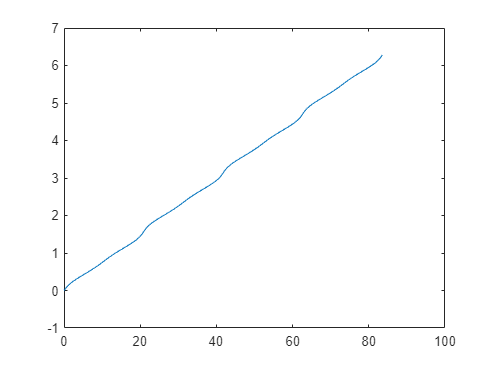

theta = 0:step:2*pi;
ttheta = spline(t,theta,tt);
plot(tt,ttheta)

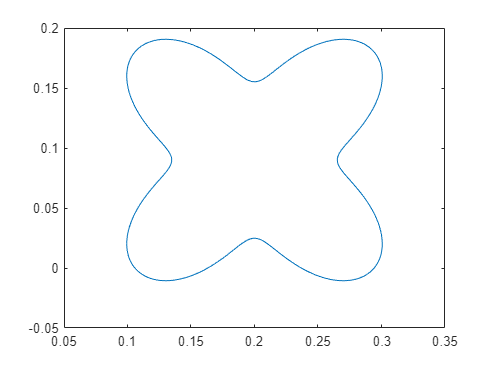

x = double(subs(x));
y = double(subs(y));
plot(x,y);

t_total = 10

t_total = 10

t = linspace(0,2*t_total,2*n)

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1001    0.1101    0.1201    0.1301    0.1401    0.1501    0.1601    0.1701    0.1801    0.1901    0.2001    0.2101    0.2201    0.2301    0.2401    0.2501    0.2601    0.2701    0.2801    0.2901    0.3002    0.3102    0.3202    0.3302    0.3402    0.3502    0.3602    0.3702    0.3802    0.3902    0.4002    0.4102    0.4202    0.4302    0.4402    0.4502    0.4602    0.4702    0.4802    0.4902


q2 = [ci_q2(x,y) ci_q2(x,y)]

q2 =     1.4250    1.4239    1.4226    1.4211    1.4195    1.4177    1.4158    1.4137    1.4115    1.4092    1.4066    1.4040    1.4011    1.3982    1.3950    1.3917    1.3883    1.3847    1.3810    1.3771    1.3730    1.3688    1.3645    1.3600    1.3553    1.3505    1.3456    1.3405    1.3353    1.3299    1.3244    1.3187    1.3129    1.3070    1.3010    1.2948    1.2884    1.2820    1.2754    1.2687    1.2619    1.2549    1.2479    1.2407    1.2334    1.2260    1.2185    1.2109    1.2032    1.1954


vq2 = [0 diff(q2)./diff(t)]

vq2 =          0   -0.1164   -0.1311   -0.1460   -0.1609   -0.1760   -0.1910   -0.2062   -0.2214   -0.2366   -0.2519   -0.2672   -0.2825   -0.2979   -0.3132   -0.3285   -0.3438   -0.3591   -0.3743   -0.3895   -0.4047   -0.4197   -0.4347   -0.4497   -0.4645   -0.4792   -0.4939   -0.5084   -0.5228   -0.5370   -0.5511   -0.5651   -0.5789   -0.5925   -0.6059   -0.6192   -0.6322   -0.6451   -0.6577   -0.6701   -0.6823   -0.6942   -0.7058   -0.7172   -0.7284   -0.7392   -0.7497   -0.7600   -0.7699   -0.7795


aq2 = [0 diff(vq2)./diff(t)]

aq2 =          0  -11.6319   -1.4753   -1.4847   -1.4933   -1.5010   -1.5079   -1.5140   -1.5192   -1.5235   -1.5270   -1.5295   -1.5313   -1.5321   -1.5321   -1.5312   -1.5294   -1.5267   -1.5231   -1.5186   -1.5133   -1.5070   -1.4998   -1.4918   -1.4828   -1.4729   -1.4622   -1.4505   -1.4379   -1.4244   -1.4100   -1.3947   -1.3785   -1.3614   -1.3433   -1.3244   -1.3045   -1.2837   -1.2620   -1.2393   -1.2157   -1.1912   -1.1657   -1.1392   -1.1118   -1.0835   -1.0541   -1.0238   -0.9924   -0.9601


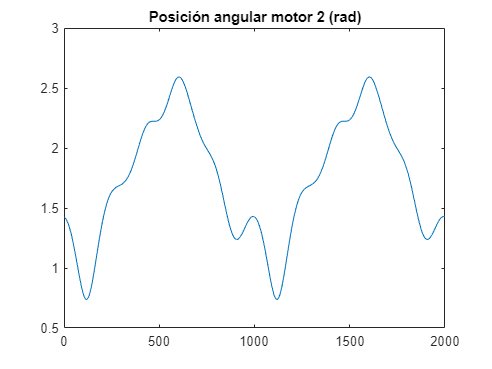

plot(q2);
title('Posición angular motor 2 (rad)')

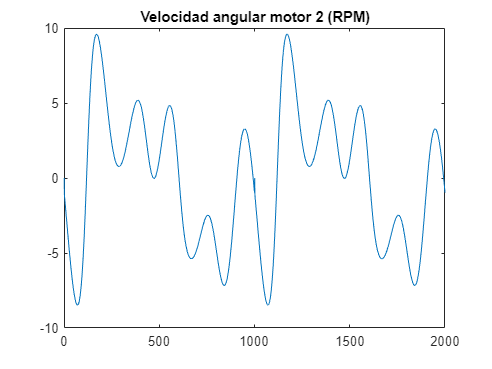

plot(vq2*30/pi);
title('Velocidad angular motor 2 (RPM)')

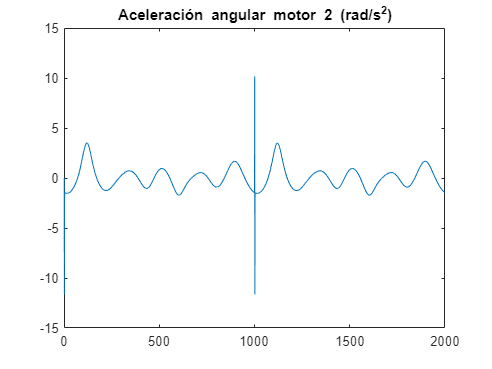

plot(aq2);
title('Aceleración angular motor 2 (rad/s^2)')


q2aux = ci_q2(x,y)

q2aux =     1.4250    1.4239    1.4226    1.4211    1.4195    1.4177    1.4158    1.4137    1.4115    1.4092    1.4066    1.4040    1.4011    1.3982    1.3950    1.3917    1.3883    1.3847    1.3810    1.3771    1.3730    1.3688    1.3645    1.3600    1.3553    1.3505    1.3456    1.3405    1.3353    1.3299    1.3244    1.3187    1.3129    1.3070    1.3010    1.2948    1.2884    1.2820    1.2754    1.2687    1.2619    1.2549    1.2479    1.2407    1.2334    1.2260    1.2185    1.2109    1.2032    1.1954


q1 = [ci_q1(x,y,q2aux) ci_q1(x,y,q2aux)]

q1 =    -0.3620   -0.3601   -0.3581   -0.3561   -0.3540   -0.3518   -0.3497   -0.3474   -0.3451   -0.3427   -0.3403   -0.3378   -0.3353   -0.3326   -0.3299   -0.3272   -0.3244   -0.3215   -0.3185   -0.3155   -0.3124   -0.3092   -0.3060   -0.3026   -0.2992   -0.2957   -0.2922   -0.2886   -0.2848   -0.2811   -0.2772   -0.2732   -0.2692   -0.2651   -0.2609   -0.2567   -0.2523   -0.2479   -0.2434   -0.2388   -0.2342   -0.2295   -0.2247   -0.2198   -0.2148   -0.2098   -0.2047   -0.1995   -0.1943   -0.1890


vq1 = [0 diff(q1)./diff(t)]

vq1 =          0    0.1930    0.1979    0.2030    0.2082    0.2136    0.2192    0.2249    0.2307    0.2366    0.2427    0.2490    0.2553    0.2618    0.2684    0.2752    0.2820    0.2889    0.2960    0.3031    0.3104    0.3177    0.3251    0.3326    0.3401    0.3478    0.3554    0.3631    0.3709    0.3787    0.3865    0.3944    0.4023    0.4101    0.4180    0.4259    0.4337    0.4415    0.4493    0.4571    0.4648    0.4724    0.4800    0.4875    0.4950    0.5023    0.5096    0.5167    0.5237    0.5306


aq1 = [0 diff(vq1)./diff(t)]

aq1 =          0   19.2868    0.4937    0.5089    0.5240    0.5389    0.5536    0.5681    0.5822    0.5961    0.6097    0.6230    0.6359    0.6484    0.6605    0.6722    0.6834    0.6942    0.7045    0.7143    0.7235    0.7322    0.7403    0.7478    0.7547    0.7610    0.7667    0.7716    0.7759    0.7796    0.7825    0.7846    0.7861    0.7868    0.7868    0.7860    0.7844    0.7820    0.7789    0.7749    0.7702    0.7646    0.7582    0.7510    0.7430    0.7341    0.7244    0.7138    0.7024    0.6901


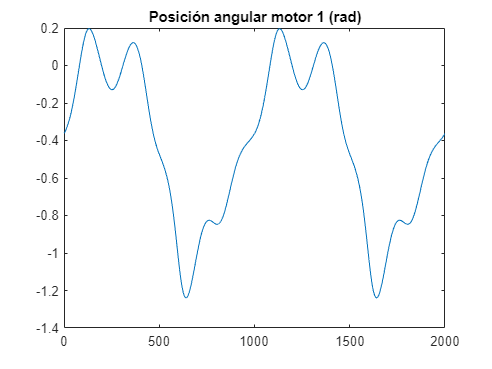

plot(q1);
title('Posición angular motor 1 (rad)')

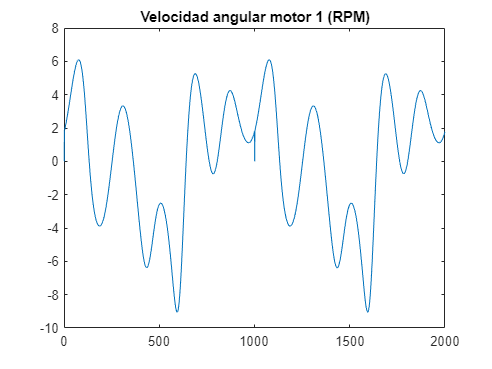

plot(vq1*30/pi);
title('Velocidad angular motor 1 (RPM)')

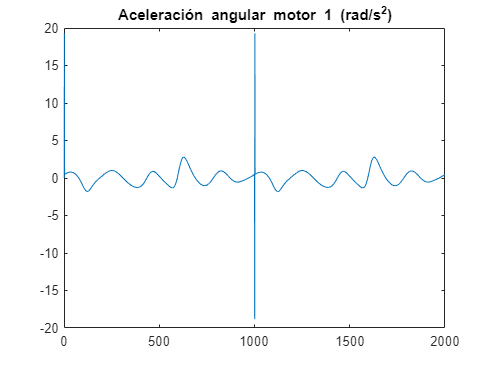

plot(aq1);
title('Aceleración angular motor 1 (rad/s^2)')


TAU = zeros(2,2*n)

TAU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


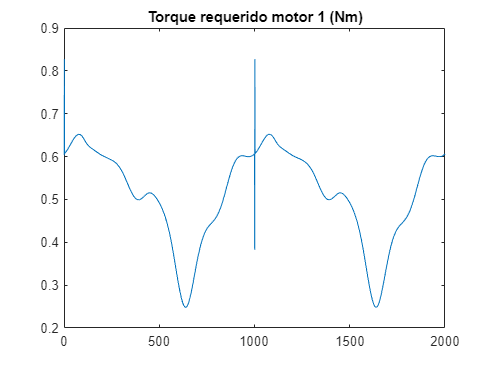

for i = 1:2*n
    TAU(:,i) = tau(q1(i),q2(i),vq1(i),vq2(i),aq1(i),aq2(i));
end
plot(TAU(1,:))
title('Torque requerido motor 1 (Nm)')

TRMS1 = rms(TAU(1,:))

TRMS1 = 0.5241

Tmax1 = max(TAU(1,:))

Tmax1 = 0.8272

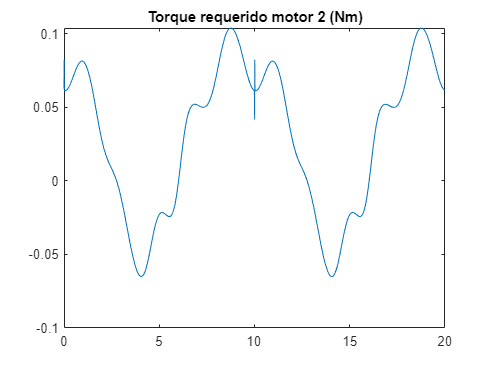


plot(t,TAU(2,:))
title('Torque requerido motor 2 (Nm)')

TRMS2 = rms(TAU(2,:))

TRMS2 = 0.0584

Tmax2 = max(TAU(2,:))

Tmax2 = 0.1038


pos1 = [t; q1]'

pos1 =          0   -0.3620
    0.0100   -0.3601
    0.0200   -0.3581
    0.0300   -0.3561
    0.0400   -0.3540
    0.0500   -0.3518
    0.0600   -0.3497
    0.0700   -0.3474
    0.0800   -0.3451
    0.0900   -0.3427


pos2 = [t; q2]'

pos2 =          0    1.4250
    0.0100    1.4239
    0.0200    1.4226
    0.0300    1.4211
    0.0400    1.4195
    0.0500    1.4177
    0.0600    1.4158
    0.0700    1.4137
    0.0800    1.4115
    0.0900    1.4092


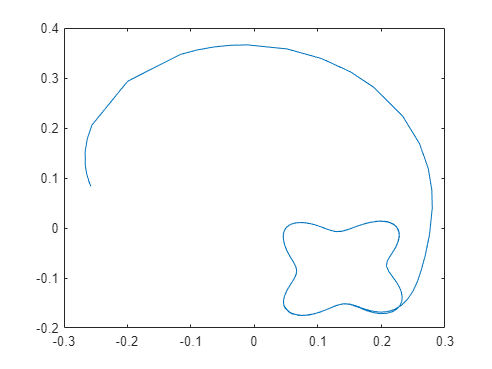

plot(posx, posy)